# Calculating Taylor Series in MATLAB

Using MATLAB's Symbolic Calculus and Algebra in order to calculate Taylor Series for functions. A Taylor Series is an infinitely long series of polynomials that can be used to approximate a function for a certain radius of convergence. Taylor Series take the form $\sum_{i=0}^n \frac{\left(f^{\left(i\right)} \left(c\right)\right)}{i!}{\left(x-c\right)}^i$. This script generates the first few terms for the Taylor Series of $\sin \left(x\right)$, and plots it against sin(x).

Author: Will Cerne

syms x; %define x as a variable

c = 0; %center of the Taylor Series

nofterms = 15; %number of terms in the Taylor Series.

func = sin(x); %function of x

taylor = 0; %sets a variable taylor equal to zero so we can create a for loop and start adding terms to it.

for i = 1:nofterms;
    funcdiff = diff(func,i,x); % ith derivative of func
    funcdiffc = subs(funcdiff,x,c); % ith derivative of func evaluated at the center c
    taylor = taylor + (funcdiffc/factorial(i))*(x-c)^i; %calculating terms of the taylor series
end

taylor

$$taylor = -\frac{x^{15}}{1307674368000}+\frac{x^{13}}{6227020800}-\frac{x^{11}}{39916800}+\frac{x^{9}}{362880}-\frac{x^{7}}{5040}+\frac{x^{5}}{120}-\frac{x^{3}}{6}+x$$

Let's approximate the value of $\frac{\sqrt{3}}{2}$ using this power series. We know that $\sin \left(\frac{\pi }{3}\right)=\frac{\sqrt{3}}{2}$.

guesssym = subs(taylor,x,pi/3); %evaluating our taylor series at pi/3
guess = double(guesssym); %changing the output from sym to double.
error = (sqrt(3)/2)-guess 

error = 6.1062e-15

The error of the Taylor Series is incredibly small, 0.000000000000061062 to be precise. Lastly, let's plot the Taylor Series against the actual function.

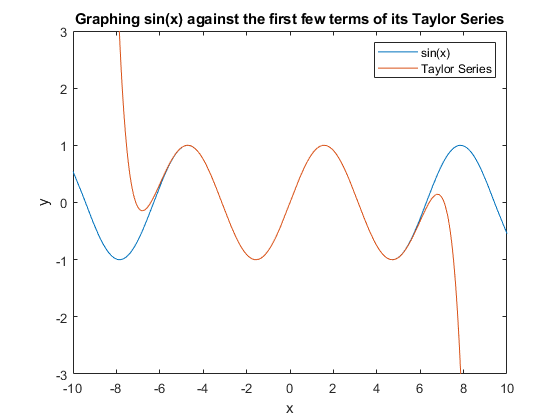

figure()
fplot(func)
hold on
fplot(taylor)
xlabel('x');ylabel('y');title('Graphing sin(x) against the first few terms of its Taylor Series');
legend('sin(x)','Taylor Series')
xlim([-10 10]);
ylim([-3.00 3.00]);

As seen from the graph, the Taylor Series appears to be a perfect fit for sin(x) from $-5<x<5$. If we zoom out on the plot, the Taylor Series starts to fail at around $x \pm 6$. The radius of convergence for the power series of $sin(x)$is $R=\infty$, so if we were to calculate more terms for the series, the fit would get more accurate.